b

clc, clearvars, close all

x = [1 2 3 4 5];
y = [0.125 0.470 1.451 8.263 31.960];

u = ones(size(x))

u =      1     1     1     1     1



figure;
plot(x, y, '*');
hold on;

c

A = [x*x' x*u'; x*u' u*u']

A =     55    15
    15     5


r = [x*y' ; u*y']

r =   198.2700
   42.2690



z = A \ r

z =     7.1463
  -12.9851


a = z(1)

a = 7.1463

b = z(2)

b = -12.9851


y_lin = a*x + b

y_lin =    -5.8388    1.3075    8.4538   15.6001   22.7464



err_lin = abs(y - y_lin)

err_lin =     5.9638    0.8375    7.0028    7.3371    9.2136


max_err_lin = max(err_lin)

max_err_lin = 9.2136


plot(x, y_lin, 'm--');

d

Y = log(y)

Y =    -2.0794   -0.7550    0.3723    2.1118    3.4645



A1 = [x*x' x*u'; x*u' u*u']

A1 =     55    15
    15     5


r1 = [x*Y' ; u*Y']

r1 =    23.2968
    3.1141



z1 = A1 \ r1

z1 =     1.3955
   -3.5636


a1 = z1(1);
b1 = z1(2);

y_exp = exp(b1) * exp(a1*x);

err_exp = abs(y - y_exp);
max_err_exp = max(err_exp);

plot(x, y_exp, 'c-');

e

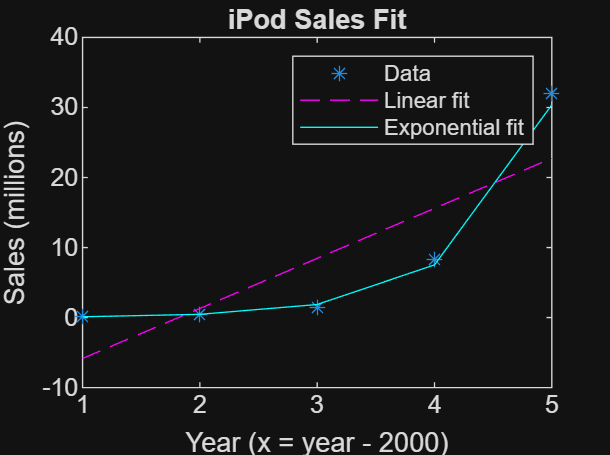

legend('Data', 'Linear fit', 'Exponential fit');
xlabel('Year (x = year - 2000)');
ylabel('Sales (millions)');
title('iPod Sales Fit');

f

% 2006 (x = 6)
y_2006 = exp(b1) * exp(a1*6)

y_2006 = 122.6349


% 2015 (x = 15)
y_2015 = exp(b1) * exp(a1*15)

y_2015 = 3.4914e+07